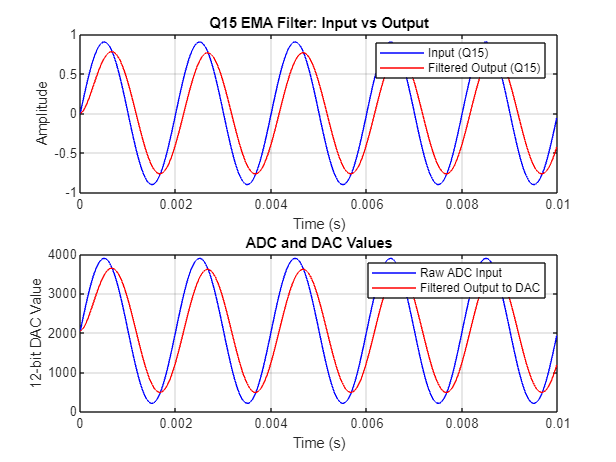

clc;                  % Clear command window
clear;                % Clear workspace variables

% ----------------------------------------
% Parameters
% ----------------------------------------
Fs = 48000;           % Sampling rate in Hz
T = 0.01;             % Duration of the signal in seconds
N = Fs * T;           % Number of samples (480)
f1 = 500;             % Frequency of the test sinewave in Hz
t = (0:N-1)/Fs;       % Time vector from 0 to T with step size 1/Fs

% ----------------------------------------
% Generate input test signal
% ----------------------------------------
x_float = 0.9 * sin(2*pi*f1*t);                  % Create a sine wave with amplitude 0.9
x_adc = uint16((x_float + 1.0) * 2048);          % Convert float signal to 12-bit ADC values (range 0–4095)

% ----------------------------------------
% Q15 Constants
% ----------------------------------------
Q15_MAX = 32767;                                  % Maximum Q15 value
Q15_MIN = -32768;                                 % Minimum Q15 value
alpha = 0.1;                                      % EMA smoothing factor
ALPHA_Q15 = int16(round(alpha * 32767));          % α converted to Q15 format
ONE_MINUS_ALPHA_Q15 = int16(round((1 - alpha) * 32767));  % (1−α) converted to Q15 format

% ----------------------------------------
% Buffers for signal processing
% ----------------------------------------
x_q15 = zeros(1, N, 'int16');    % Allocate array for Q15 input signal
y_q15 = zeros(1, N, 'int16');    % Allocate array for Q15 filtered output
y_prev = int16(0);               % Initialize previous output sample to 0

% ----------------------------------------
% Real-Time EMA Filter Simulation (Q15 Arithmetic)
% ----------------------------------------
for n = 1:N
    % ---- ADC to Q15 Conversion ----
    adc_val = double(x_adc(n));                          % Convert ADC value to double
    x = ((adc_val - 2048) / 2048) * 32767;               % Normalize to [-1, 1] and scale to Q15
    x = round(x);                                        % Round to nearest integer
    x = min(max(x, Q15_MIN), Q15_MAX);                   % Clamp to Q15 range
    x_q15(n) = int16(x);                                 % Store in Q15 input array

    % ---- EMA Filtering: part1 = α * x[n] ----
    mult1 = int32(ALPHA_Q15) * int32(x_q15(n));          % Multiply α in Q15 * x[n] in Q15
    mult1 = mult1 + 16384;                               % Add 2^14 for rounding
    mult1 = bitshift(mult1, -15);                        % Shift right by 15 bits (>> 15)
    mult1 = min(max(mult1, Q15_MIN), Q15_MAX);           % Clamp result to Q15 range
    part1 = int16(mult1);                                % Convert back to 16-bit integer

    % ---- EMA Filtering: part2 = (1−α) * y[n−1] ----
    mult2 = int32(ONE_MINUS_ALPHA_Q15) * int32(y_prev);  % Multiply (1−α) * previous output
    mult2 = mult2 + 16384;                               % Add for rounding
    mult2 = bitshift(mult2, -15);                        % Shift right by 15 bits
    mult2 = min(max(mult2, Q15_MIN), Q15_MAX);           % Clamp to Q15
    part2 = int16(mult2);                                % Convert to 16-bit integer

    % ---- Final EMA Output ----
    y_q15(n) = int16(part1 + part2);                     % y[n] = α*x[n] + (1−α)*y[n−1]

    % ---- Update Previous Output ----
    y_prev = y_q15(n);                                   % Store y[n] for use in next iteration
end

% ----------------------------------------
% Convert filtered Q15 signal to 12-bit DAC output
% ----------------------------------------
y_dac = zeros(1, N, 'uint16');                           % Allocate array for DAC output
for n = 1:N
    q15_val = double(y_q15(n));                          % Convert Q15 to double
    y_float = q15_val / 32767;                           % Convert Q15 to float in [-1, 1]
    y_shifted = y_float * 2048 + 2048;                   % Shift and scale to [0, 4095]
    y_dac(n) = uint16(min(max(round(y_shifted), 0), 4095)); % Clamp and convert to 12-bit DAC
end

% ----------------------------------------
% Plot Results
% ----------------------------------------
figure; set(gcf, 'Color', 'w');                          % Create new figure with white background

% ---- Plot Q15 Input and Output ----
subplot(2,1,1);                                           % First subplot
plot(t, double(x_q15)/32767, 'b'); hold on;              % Plot input Q15 signal (blue)
plot(t, double(y_q15)/32767, 'r');                       % Plot filtered Q15 signal (red)
xlabel('Time (s)');
ylabel('Amplitude');
title('Q15 EMA Filter: Input vs Output');
legend('Input (Q15)', 'Filtered Output (Q15)');
grid on;

% ---- Plot Raw ADC and Filtered DAC Output ----
subplot(2,1,2);                                           % Second subplot
plot(t, x_adc, 'b'); hold on;                            % Plot raw ADC values
plot(t, y_dac, 'r');                                     % Plot filtered DAC output
xlabel('Time (s)');
ylabel('12-bit DAC Value');
title('ADC and DAC Values');
legend('Raw ADC Input', 'Filtered Output to DAC');
grid on;